# Week 10-11 Workshop - Spike Waveform Classification

In this week's workshop you will use a decision tree to classify spike waveforms extracted from neural data. There are a few identifable signatures of  spike waveforms that are used to classify different types of neurons. Examples of different waveforms can be found in WaveformDecisionTree.pdf on LMS.

## 1. Set data path & load data filenames

- Download the WaveformDataDistribution.zip, and Waveform_Excel_AllCells.xlsx from the following link https://drive.google.com/drive/folders/1-2ESSX1kp4gmHrcmB30vKryZsmUYSg-d?usp=sharing

- Set up a working directory with the folder WaveformDataDistribution, the file Waveform_Excel_AllCells.xlsx, and this BMEN90035WorkshopWeek10_11.m file.

- Run the following commands to add the WaveformDataDistribution to your wd path, and read in the Waveform_Excel_AllCells.xlsx to your workspace.

currentFolder = pwd;                            % set wd to current folder
addpath(genpath('WaveformDataDistribution'));   % add subfolder to path

CellExcel  = 'Waveform_Excel_AllCells.xlsx';    % read in excel cell file
[~,~, raw] = xlsread(CellExcel);
headers    = raw(1, :);                         % separate headers
raw(1, :)  = [];                                % remove headers
CellTable  = cell2table(raw(:, 1:length(headers)), 'VariableNames', headers); % combine headers & data into cell table array

- The folder WaveformDataDistribution contains 976 .mat data files. These files contain spike waveforms within the struct 'wf'. These waveforms have negative going peaks that are time-centered on zero and the domain of each is (-30 60) samples. 

- Note that there are three waveform data types within wf, 'raw', '1Cluster' and 'filtered'. For this workshop we are going to be using all 3, but not necassarily distinugising between them. The reason we note the differed types is due to the extraction process outlined in code lines 49-67 which uses an if statement to extract the correct waveform data for each .mat file. 

- Below, there is code that extracts a single 'waveform' vector (amplitude in microvolts, time in samples from -30 to 60) for each of the 976 spike waveform files. This waveform vector is a 91x1 double, and is what you will use to extract the features of waveforms and then sort the waveforms. You can add to the code to classify waveforms where it says '%begin coding here".

## 2. Classifying waveforms (15 Marks)

Referring to W10_W11_WaveformClassificationDefinitions.pdf on the LMS, construct a decision tree algorithm that sorts the waveforms according to their features into the following categories:

- Positive

- Triphasic

- Compound

- Regular

- Fast.

**Hints**: 

- In W10_W11_WaveformClassificationDefinitions.pdf there are some definitions of waveform characteristics to help you with the calculations needed for your decision tree.

- Once you have determined what type of waveform you have, save the strings 'Positive', 'Triphasic', 'Compound', 'Regular', or 'Fast', into a cell array called Classification using code of the following form:

- The following for loop extracts each file name and then extracts the corresponding .mat file which includes the waveform for you to classify. Write your decision tree code within this loop after line 55.

threshold = 0.1;                            % .1 threshold for triphasic/compound waveforms
gradient_point = 10;                        % 10 samples after time of trough to calc endslope

CellWaveforms = [];
end_slope = [];
tp_time   = [];
tp_ratio  = [];
iwaveform = 0;
for iCell = 1:size(CellTable,1)
    %fprintf('Processing Cell id %i...\n', iCell)        % comment this line out when publishing
    % load cell filename info - give this
    Exp   = [ CellTable.Exp{iCell}];
    Track = ['Track' num2str(CellTable.Track(iCell))];
    Part  = ['Part' num2str(CellTable.Part(iCell))];
    CellID= num2str(CellTable.CellID(iCell));
    site  = CellTable.Site(iCell);
    
    % load and extract waveforms from filename info - give this
    waveform_path = fullfile(currentFolder, 'WaveformDataDistribution');
    filename = sprintf('%d %s-%s-%s-Cell_%s.mat', CellTable.Cell(iCell), Exp, Track, Part, CellID);
    load(fullfile(waveform_path, filename))
    if strcmp(CellTable.WaveformExtract{iCell}, 'raw')
        waveform = squeeze(mean(wf.waveFormsMean(:,site,:),1));
    elseif strcmp(CellTable.WaveformExtract{iCell}, '1Cluster')
        waveform = wf.Average_MaxCluster(site,:);
    elseif strcmp(CellTable.WaveformExtract{iCell}, 'filtered')
        waveform = wf.Average_AllClusters(site,:);
    end
    
    % normalise waveform with baseline
    Baseline = mean(waveform([1:10 end-9:end]));
    waveform = waveform - Baseline;
    
    % convert units to microvolts
    waveform = waveform/4;
    
    CellWaveforms(iCell,:) = waveform;             % save trough normalised waveform
    
    % decision tree
    % positive-spiking waveform
    if abs(min(waveform)) < abs(max(waveform))
        Classification{iCell,:} = 'Positive';
    else

        % waveform parameters
        [peaks, peaksid] = findpeaks(waveform);
        [trough, troughid] = min(waveform);
        waveslope = gradient(waveform);
        endslope = waveslope(troughid + 10);

        % first peak
        if find(peaksid < troughid)
            first = find(peaksid < troughid);
            first = first(end);
            firstpeak = peaks(first);
            firstpeakid = peaksid(first);
        else
            firstpeak = 0;
            firstpeakid = 1;
        end

        % second peak
        if find(peaksid > troughid)
            second = find(peaksid > troughid);
            second = second(1);
            secondpeak = peaks(second);
            secondpeakid = peaksid(second);
        else
            secondpeak = 0;
            secondpeakid = length(waveform);
        end
        
        % compound waveform
        if abs(firstpeak/trough) > 0.1 && ((secondpeakid - firstpeakid)/30 > 1)
            Classification{iCell,:} = 'Compound';
            
            % triphasic waveform
        elseif abs(firstpeak/trough) > 0.1
            Classification{iCell,:} = 'Triphasic';
            
            % regular negative-spiking waveform
        elseif endslope > 0
            Classification{iCell,:} = 'Regular';
        else
            
            % fast negative-spiking waveform
            Classification{iCell,:} = 'Fast';
        end
    end
end   

## 3a. Visualising waveform classifications (2 marks)

**Figures**:

- Figure 1: visualise the percentage of each waveform type using a histogram. 

**Note**: If you would like to use the following colour coordination for the next 3 sections the RGB maps for each are below.

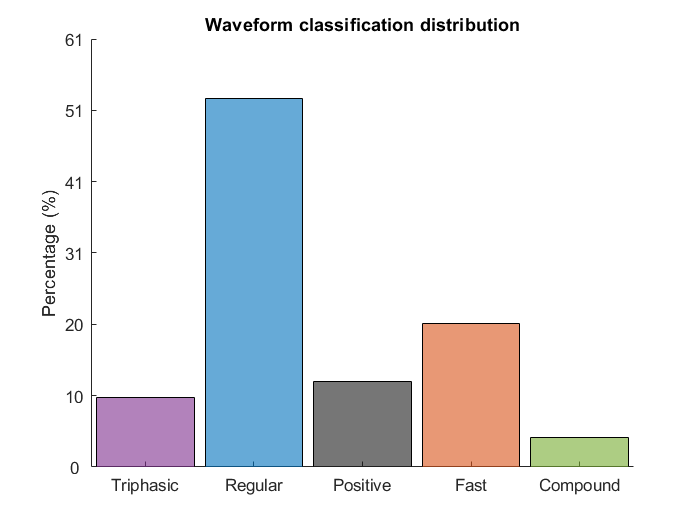

% figure 1
figure(1);
hold on

% color for classifications 
RegularColor = [0, 0.4470, 0.7410];                 % blue
FastColor    = [0.8500, 0.3250, 0.0980];            % red/orange
TriColor     = [0.4940 0.1840 0.5560];              % purple
ComColor     = [0.4660 0.6740 0.1880];              % green
PosColor     = [0.1 0.1 0.1];                       % grey

% histogram plotting
[uniquec, ~, C] = unique(Classification); 
count = histc(C, 1:numel(uniquec));

% plot each histogram separately and overlay
histogram('Categories', uniquec(1), 'BinCounts', count(1), 'FaceColor', ComColor);
histogram('Categories', uniquec(2), 'BinCounts', count(2), 'FaceColor', FastColor);
histogram('Categories', uniquec(3), 'BinCounts', count(3), 'FaceColor', PosColor);
histogram('Categories', uniquec(4), 'BinCounts', count(4), 'FaceColor', RegularColor);
histogram('Categories', uniquec(5), 'BinCounts', count(5), 'FaceColor', TriColor);

% turn y-axis into percentage
yticks = get(gca, 'YTick');
set(gca, 'YTick', yticks, 'YTickLabel', round((yticks*100)/sum(count)));
ylabel('Percentage (%)');
title('Waveform classification distribution');
hold off

## 3b. Visualising waveforms (3 marks)

**Figures**:

- Figure 2: Visualise the waveforms for each classification by plotting all waveforms within the classification to subplot(2,3,i). Normalise each waveform such that the trough takes the value of -1, i.e., waveform = -1*waveform/min(waveform). Then, calculate the mean waveform and overlay this on top. 

**Hint**:

- The following command extracts the indicies in the cell array 'Classification' (and therefore CellWaveforms) that correspond to a 'Regular' waveform. This will help in the systematic extraction and plotting of each waveform classification.

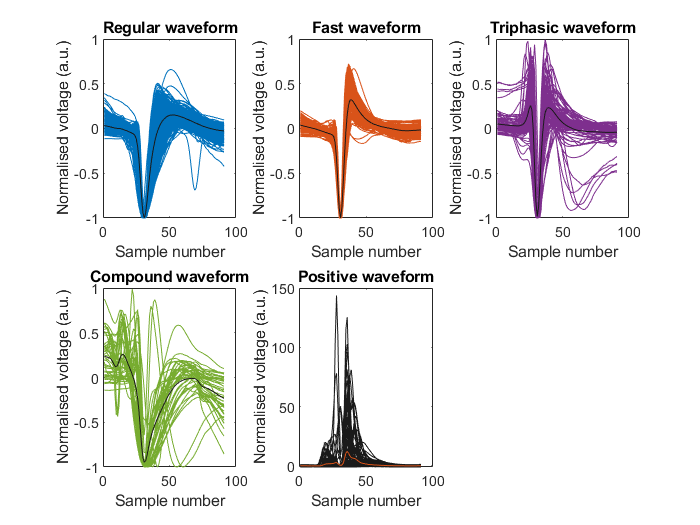

% figure 2
figure(2);

% "regular" waveform
subplot(2, 3, 1);

% indecies for the "regular" classification
idx_r = find(strcmp(Classification, 'Regular'));

% extract the waveforms
waveform = CellWaveforms(idx_r, :);

% normalisation
for i = 1:size(waveform, 1)
    waveform(i, :) = -1*waveform(i, :)/min(waveform(i, :));
end

% average waveform
avwaveform = mean(waveform, 1);

% plot the waveforms
plot(waveform', 'Color', [RegularColor 0.07]);
hold on
plot(avwaveform', 'Color', [PosColor 1]);
hold off
xlabel('Sample number');
ylabel('Normalised voltage (a.u.)');
title('Regular waveform');

% "fast" waveform
subplot(2, 3, 2);

% indecies for the "fast" classification
idx_f = find(strcmp(Classification, 'Fast'));

% extract the waveforms
waveform = CellWaveforms(idx_f, :);

% normalisation
for i = 1:size(waveform, 1)
    waveform(i, :) = -1*waveform(i, :)/min(waveform(i, :));
end

% average waveform
avwaveform = mean(waveform, 1);

% plot the waveforms
plot(waveform', 'Color', [FastColor 0.07]);
hold on
plot(avwaveform', 'Color', [PosColor 1]);
hold off
xlabel('Sample number');
ylabel('Normalised voltage (a.u.)');
title('Fast waveform');

% "triphasic" waveform
subplot(2, 3, 3);

% indecies for the "triphasic" classification
idx_t = find(strcmp(Classification, 'Triphasic'));

% extract the waveforms
waveform = CellWaveforms(idx_t, :);

% normalisation
for i = 1:size(waveform, 1)
    waveform(i, :) = -1*waveform(i, :)/min(waveform(i, :));
end

% average waveform
avwaveform = mean(waveform, 1);

% plot the waveforms
plot(waveform', 'Color', [TriColor 0.07]);
hold on
plot(avwaveform, 'Color', [PosColor 1]);
hold off
xlabel('Sample number');
ylabel('Normalised voltage (a.u.)');
title('Triphasic waveform');

% "compound" waveform
subplot(2, 3, 4);

% indecies for the "compound" classification
idx_c = find(strcmp(Classification, 'Compound'));

% extract the waveforms
waveform = CellWaveforms(idx_c, :);

% normalisation
for i = 1:size(waveform, 1)
    waveform(i, :) = -1*waveform(i, :)/min(waveform(i, :));
end

% average waveform
avwaveform = mean(waveform, 1);

% plot the waveforms
plot(waveform', 'Color', [ComColor 0.07]);
hold on
plot(avwaveform', 'Color', [PosColor 1]);
hold off
xlabel('Sample number');
ylabel('Normalised voltage (a.u.)');
title('Compound waveform');

% "positive" waveform
subplot(2, 3, 5);

% indecies for the "positive" classification
idx_p = find(strcmp(Classification, 'Positive'));

% extract the waveforms
waveform = CellWaveforms(idx_p, :);

% normalisation
for i = 1:size(waveform, 1)
    waveform(i, :) = -1*waveform(i, :)/min(waveform(i, :));
end

% average waveform
avwaveform = mean(waveform, 1);

% plot the waveforms
plot(waveform', 'Color', [PosColor 0.07]);
hold on
plot(avwaveform', 'Color', [FastColor 1]);
hold off
xlabel('Sample number');
ylabel('Normalised voltage (a.u.)');
title('Positive waveform');

- Use the following code to plot all waveforms as transparent lines (0.07), and a block line (1) for the mean waveform to distinguish them. See the following code for a hint.

## 4. Principal components of waveforms (5 marks)

- Calculate the first 3 principal components over all the waveforms in CellWaveforms. Ensure that the sign of the eigenvectors is such that the first sample is greater than the last sample. (No need to normalise waveforms in this question)

% take the mean
for i = 1:size(CellWaveforms, 1)
    CellWaveforms(i, :) = CellWaveforms(i, :) - mean(CellWaveforms(i, :));
end

% prepare the matrix
square = CellWaveforms'*CellWaveforms;

% number of components
n = 3;

% eigenvector/values extraction
[V, D] = eigs(square, n);

% sign change for the eigenvectors
for iv = 1:n
    V(:,iv) = sign(V(1,iv)-V(end,iv))*V(:,iv);
end

**Figures**:

- Figure 3: Plot the principal component waveforms [$\mu V$] vs. time [$s$].

- Figure 4,5,6: Project waveforms onto the principal components & plot in PC space using a scatter plot, i.e., on Figure 4 plot PC 1 vs PC 2, Figure 5 plot PC 1 vs PC 3, and Figure 6plot PC 2 vs PC 3. Then, overlay the colors corresponding to each classification given in 3b. **Hint**: To systematically plot each waveform classification with the associated color see Class Ex 8_2.

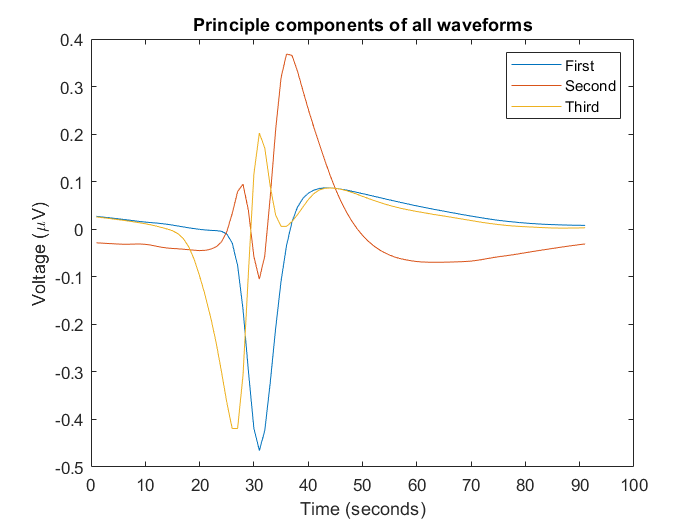

% figure 3
figure(3);

% plotting
plot(V);
xlabel('Time (seconds)');
ylabel('Voltage (\muV)');
title('Principle components of all waveforms');
legend('First','Second','Third');

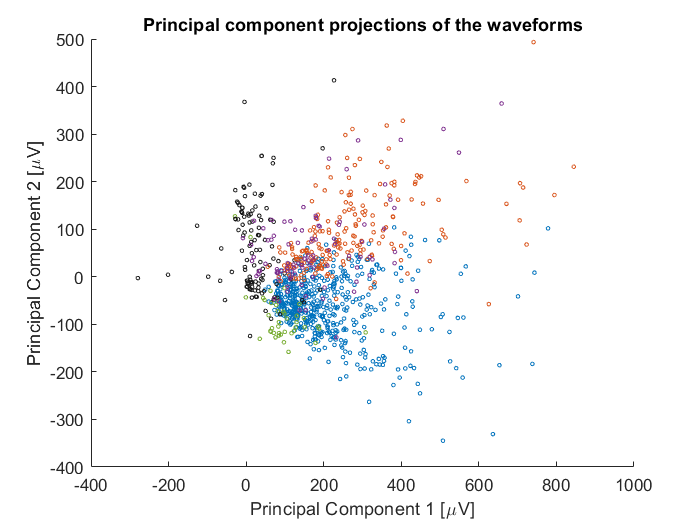


% figure 4
figure(4);

% some manipulations
coeff = CellWaveforms*V;

% plotting
scatter(coeff(idx_r, 1), coeff(idx_r, 2), 5, 'MarkerEdgeColor', RegularColor);
hold on
scatter(coeff(idx_c, 1), coeff(idx_c, 2), 5, 'MarkerEdgeColor', ComColor);
hold on
scatter(coeff(idx_p, 1), coeff(idx_p, 2), 5, 'MarkerEdgeColor', PosColor);
hold on
scatter(coeff(idx_f, 1), coeff(idx_f, 2), 5, 'MarkerEdgeColor', FastColor);
hold on
scatter(coeff(idx_t, 1), coeff(idx_t, 2), 5, 'MarkerEdgeColor', TriColor);
hold off
xlabel('Principal Component 1 [\muV]');
ylabel('Principal Component 2 [\muV]');
title('Principal component projections of the waveforms');

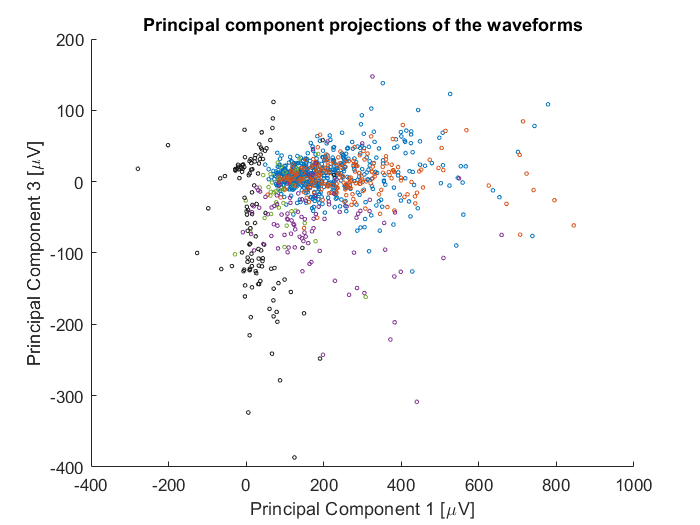


% figure 5
figure(5);

% some manipulations
coeff = CellWaveforms*V;

% plotting
scatter(coeff(idx_r, 1), coeff(idx_r, 3), 5, 'MarkerEdgeColor', RegularColor);
hold on
scatter(coeff(idx_c, 1), coeff(idx_c, 3), 5, 'MarkerEdgeColor', ComColor);
hold on
scatter(coeff(idx_p, 1), coeff(idx_p, 3), 5, 'MarkerEdgeColor', PosColor);
hold on
scatter(coeff(idx_f, 1), coeff(idx_f, 3), 5, 'MarkerEdgeColor', FastColor);
hold on
scatter(coeff(idx_t, 1), coeff(idx_t, 3), 5, 'MarkerEdgeColor', TriColor);
hold off
xlabel('Principal Component 1 [\muV]');
ylabel('Principal Component 3 [\muV]');
title('Principal component projections of the waveforms');

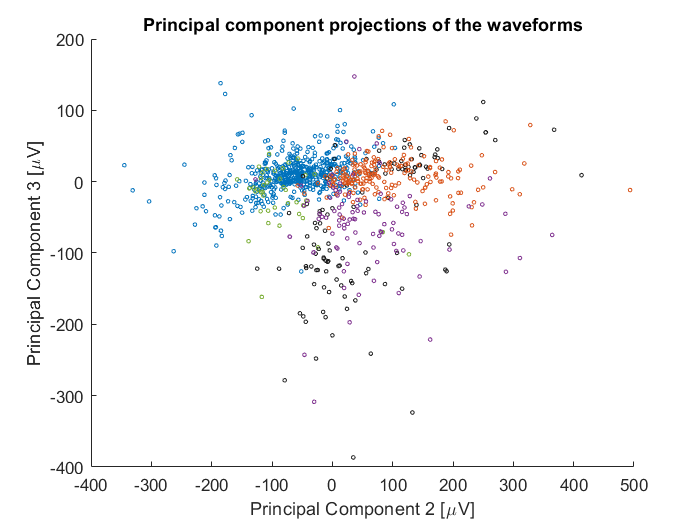


% figure 6
figure(6);

% some manipulations
coeff = CellWaveforms*V;

% plotting
scatter(coeff(idx_r, 2), coeff(idx_r, 3), 5, 'MarkerEdgeColor', RegularColor);
hold on
scatter(coeff(idx_c, 2), coeff(idx_c, 3), 5, 'MarkerEdgeColor', ComColor);
hold on
scatter(coeff(idx_p, 2), coeff(idx_p, 3), 5, 'MarkerEdgeColor', PosColor);
hold on
scatter(coeff(idx_f, 2), coeff(idx_f, 3), 5, 'MarkerEdgeColor', FastColor);
hold on
scatter(coeff(idx_t, 2), coeff(idx_t, 3), 5, 'MarkerEdgeColor', TriColor);
hold off
xlabel('Principal Component 2 [\muV]');
ylabel('Principal Component 3 [\muV]');
title('Principal component projections of the waveforms');

**Interpretation**:

- **Q:** How well does the PC analysis distinguish the different waveform types? Is this method sufficient to categorise waveforms types based on a clustering algorithm? Explain your answer.

Overall the PC analysis does a rather poor job at distinguishing different waveforms, as there is a lot of overlap between the data points. Therefore, the method is not sufficient at waveform categorisation. It relies only on the 3 principal components, while there are 5 types of waveform present in the file. Possibly expanding the PCAs to accomodate these 5 features would yield a better result. 